# 清空数据

clc 
clear

## 初始化网格

global Nx Ny; %#ok<GVMIS>
Nx = 400; Ny = 400;
mesh = ConstuctMesh([Nx,Ny],[1,1]);

## 初始化物理参数

k = 10;

## 初始化物理场

T = generatefield(mesh,fieldDimension.vol,fieldType.scalar);
U = generatefield(mesh,fieldDimension.vol,fieldType.vector);

## 物理场赋值

T = initialFieldValue(T,0);
U = initialFieldValue(U,[1,1,0]);

## 初始化边界条件

T = setBoundaryCondition(T,1,BCType.Dirichlet,BCSelect.w);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.e);
T = setBoundaryCondition(T,0,BCType.Dirichlet,BCSelect.s);
T = setBoundaryCondition(T,0,BCType.Neumann,BCSelect.n);

U = setBoundaryCondition(U,[1,1,0],BCType.Dirichlet,BCSelect.w);
U = setBoundaryCondition(U,0,BCType.Neumann,BCSelect.e);
U = setBoundaryCondition(U,0,BCType.Neumann,BCSelect.s);
U = setBoundaryCondition(U,0,BCType.Neumann,BCSelect.n);

## 初始中间变量场

phi = generatefield(mesh,fieldDimension.face,fieldType.scalar);
phi = calculatePhi(mesh,phi,U);

## 初始算子

div_T = div_fvm(mesh,phi,divScheme.upwind,T);

## 矩阵组装和求解

tic
[Matrix_T,T] = matrixSystem(T,div_T,'+',IS.solve);
toc

历时 0.028162 秒。


## 后处理

AT = fullMatrix(T);

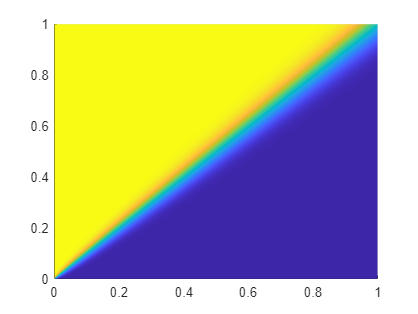

RESULT = outputField(mesh,outputSelect.smooth,T);